Code-01:

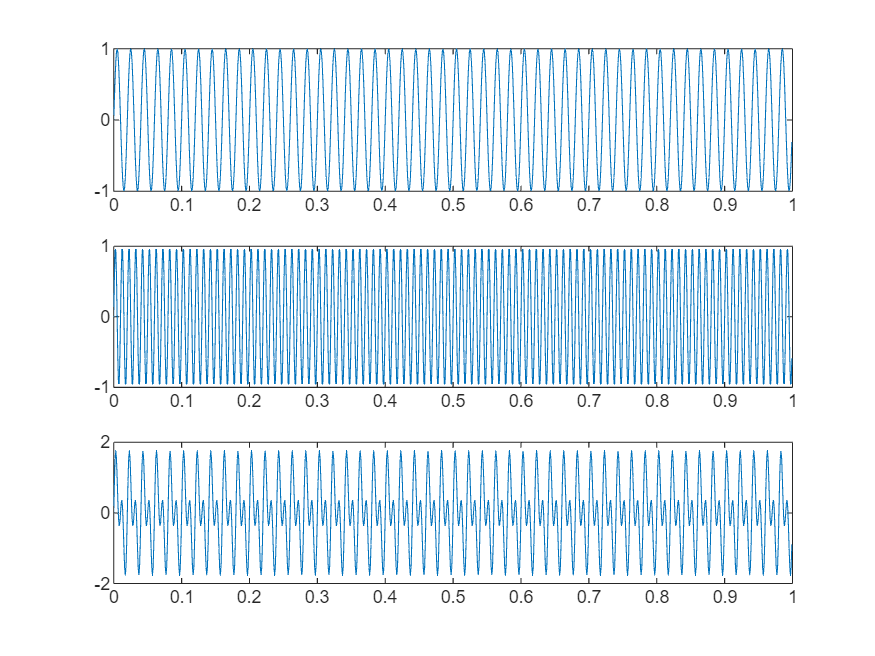

clear all
clc
% Sampling parameters
Fs = 1000;          % Sampling frequency (Hz)
T = 1;              % Time Period
t = 0:1/Fs:T-1/Fs;
f1 = 50;
f2 = 100;
x1 = sin(2*pi*f1*t);
x2 = sin(2*pi*f2*t);
% New Signal
x = x1 + x2;
% Plot the individual and combined signals
figure;
subplot(3,1,1);
plot(t, x1);
subplot(3,1,2);
plot(t, x2);
subplot(3,1,3);
plot(t, x);

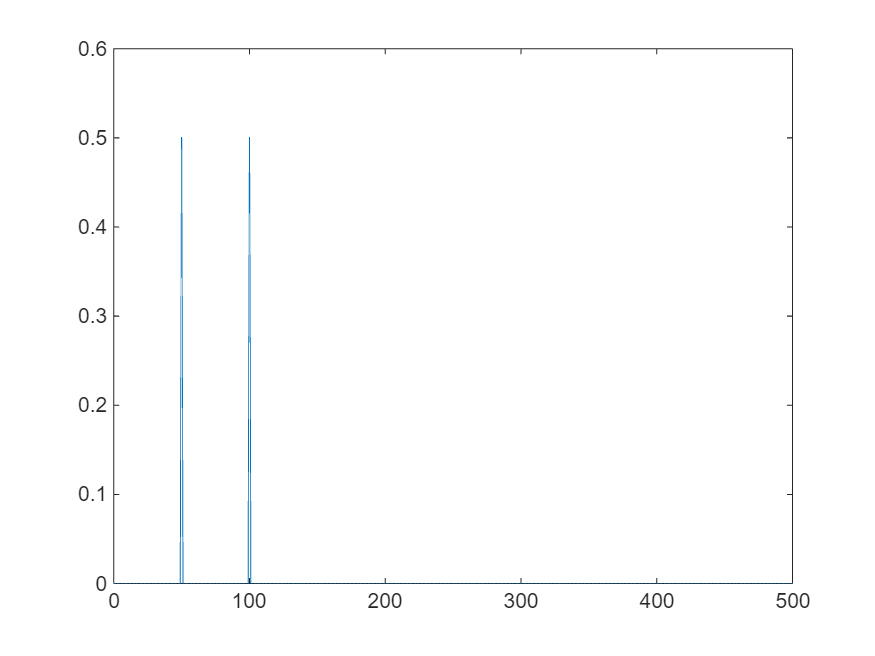

% Compute and plot the frequency spectrum
N = length(x);
X = fft(x);                     % FFT of combined signal
X_mag = abs(X)/N;               % Normalize magnitude
f = (0:N-1)*(Fs/N);             % Frequency vector
% Plot only positive frequencies
half = floor(N/2);
figure;
plot(f(1:half), X_mag(1:half));

Code-02:

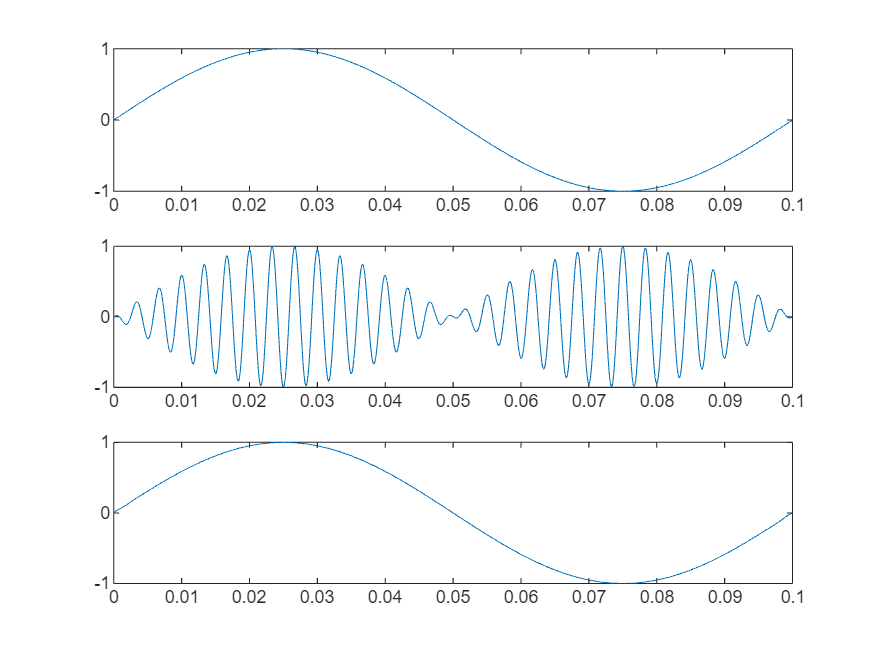

% Initialization of Parameters
T = 0.1;
fs = 8000; % Sampling Frequency
t = 0:1/fs:T; % Taking 1000 sample points between 0 to 0.1 sec
Vm = 1; % Amplitude
fm = 10; % Modulating signal frequency
m = Vm * sin(2 * pi * fm * t); % Modulating Signal
% ----- AM Modulation -----
fc = 300; % Carrier Signal
v = ammod(m, fc, fs); % Modulated Signal
% ----- AM Demodulation -----
mr = amdemod(v, fc, fs); % Demodulated Signal
% ----- Plotting Signals -----
figure(1);
subplot(3,1,1);plot(t, m);
subplot(3,1,2);plot(t,v);
subplot(3,1,3);plot(t,mr);

Code-03:

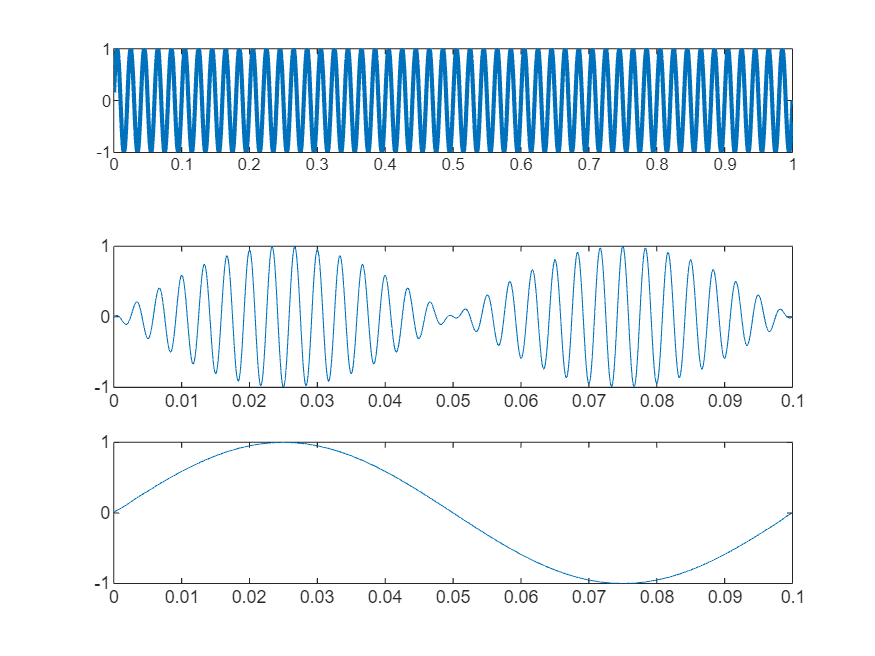

% Initialization of parameters
fs = 2000;         % Sampling frequency
f = 5;             % Signal frequency
fc = 50;           % Carrier frequency
N = 2000;          % Use 1 sec of data
t = (1:N)/fs;      % Time axis for plotting
% ----- AM Modulation -----
w = 2*pi*fc*t;     % Carrier frequency = 250 Hz
w1 = 2*pi*f*t;     % Signal frequency = 5 Hz
vc = sin(w);
figure(1);
subplot(4,1,1)
plot(t, vc, 'LineWidth', 2);

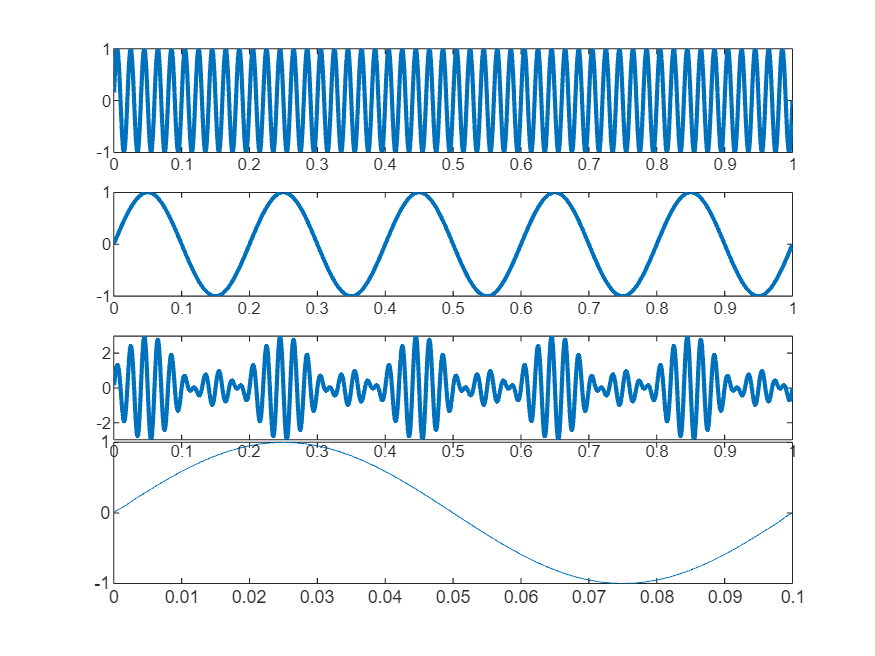

vsig = sin(w1);
figure(1);
subplot(4,1,2)
plot(t, vsig, 'LineWidth', 2);
vm = (1 + 2 * vsig) .* vc; % Modulation constant = 0.5
figure(1);
subplot(4,1,3)
plot(t, vm, 'LineWidth', 2); % Plot AM Signal

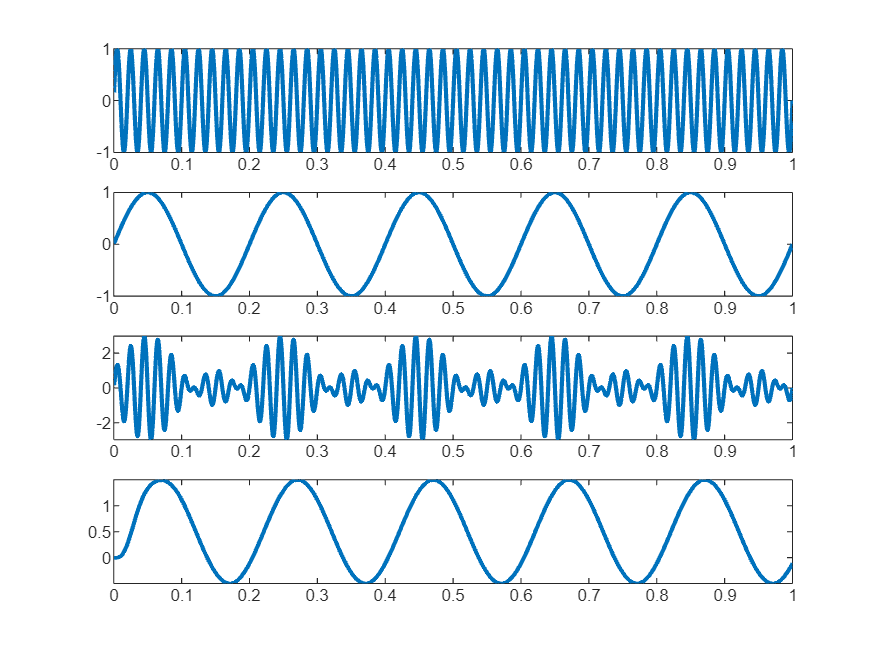

% ----- AM Demodulation -----
v1 = vc .* vm; % Multiplier
wn = 0.02; % Lowpass filter cut-off frequency
[b, a] = butter(4, wn); % Design lowpass filter
vout = filter(b, a, v1); % Apply lowpass filter
figure(1);
subplot(4,1,4);
plot(t, vout, 'LineWidth', 2);

Code-04:

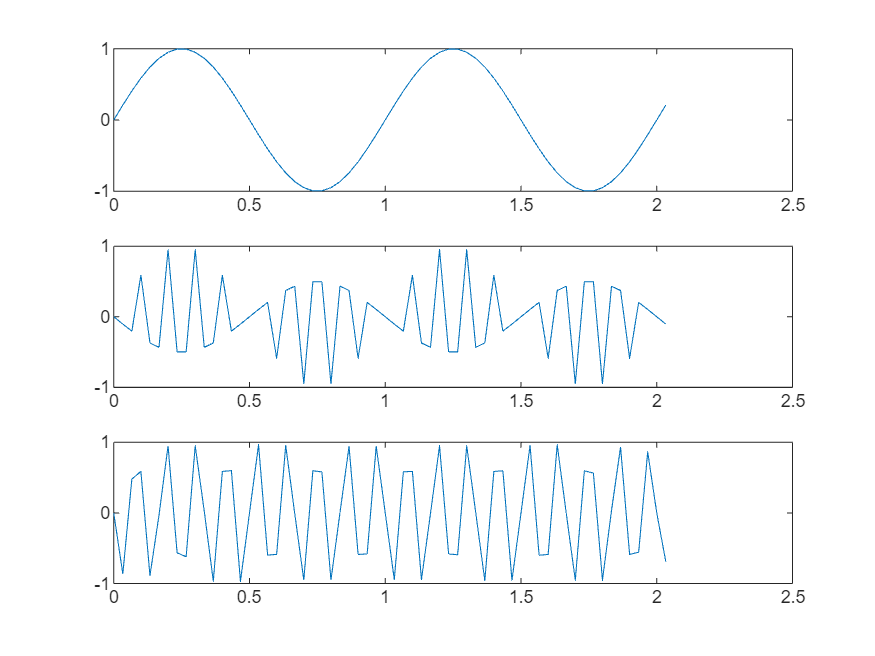

% Sample the signal 100 times per second, for 2 seconds.
Fs = 30;
t = [0:2*Fs+1]'/Fs;
Fc = 10;            % Carrier frequency
x = sin(2*pi*t);    % Sinusoidal signal
% Modulate x using single- and double-sideband AM.
ydouble = ammod(x,Fc,Fs);
ysingle = ssbmod(x,Fc,Fs);
figure(1)
subplot(3,1,1); plot(t, x);
subplot (3,1,2); plot (t, ydouble);
subplot (3,1,3); plot (t, ysingle);

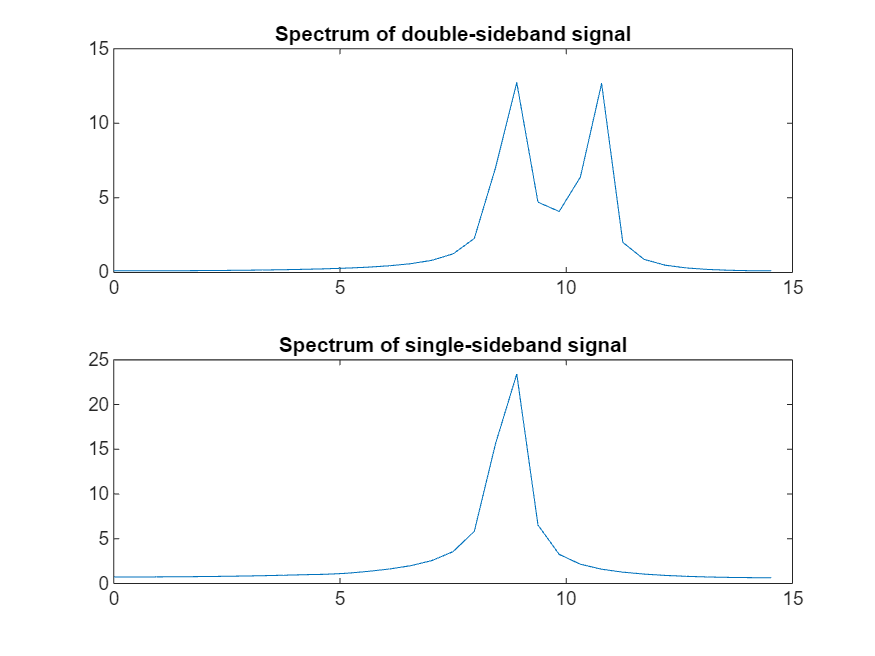

% Compute spectra of both modulated signals.
zdouble = fft(ydouble);
zdouble = abs(zdouble(1:length(zdouble)/2+1));
frqdouble = [0:length(zdouble)-1]*Fs/length(zdouble)/2;
zsingle = fft(ysingle);
zsingle = abs(zsingle(1:length(zsingle)/2+1));
frqsingle = [0:length(zsingle)-1]*Fs/length(zsingle)/2;
% Plot spectra of both modulated signals.
figure(2);
subplot(2,1,1); plot(frqdouble, zdouble);
title('Spectrum of double-sideband signal');
subplot(2,1,2); plot(frqsingle, zsingle);
title('Spectrum of single-sideband signal');

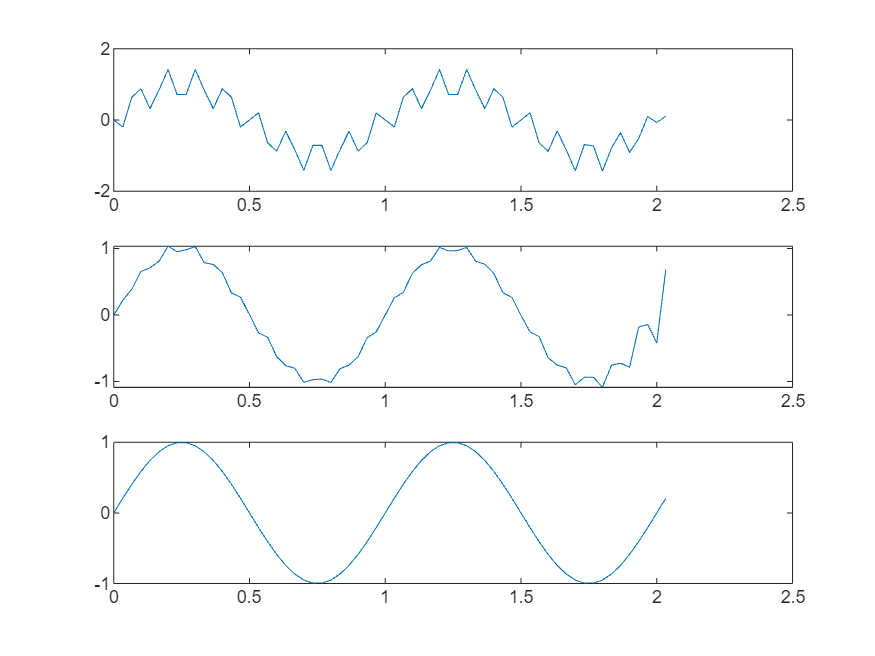

% Demodulation and plotting
ydouble1 = amdemod(ydouble, Fc, Fs);
ysingle1 = ssbdemod(ysingle, Fc, Fs);
figure(3)
subplot(3,1,1); plot(t, ydouble1);
subplot(3,1,2); plot(t, ysingle1);
subplot(3,1,3); plot(t, x);

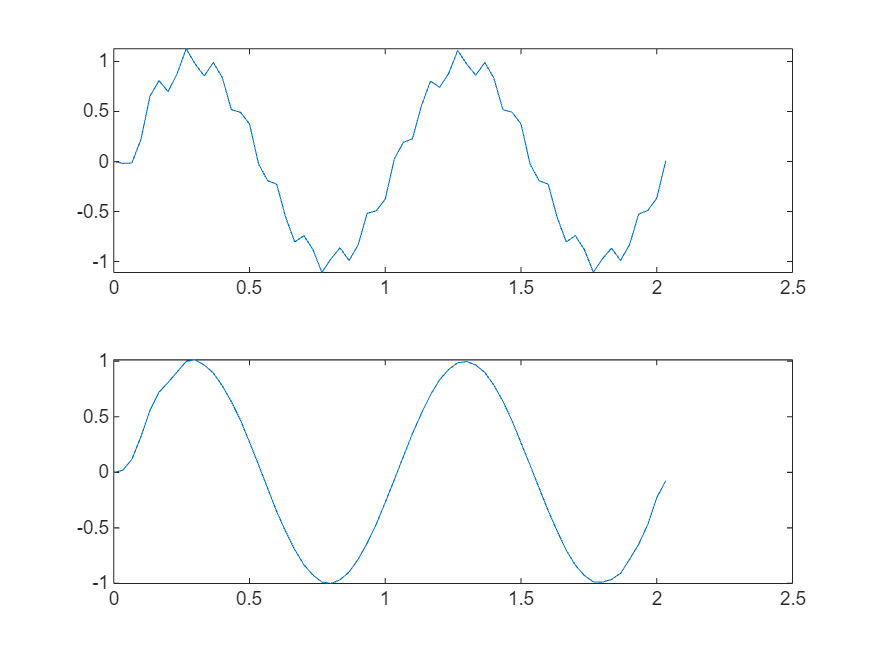

% Filtering out the noise
wn = 0.5;
[b, a] = butter(4, wn);
vout_double = filter(b, a, ydouble1);
vout_single = filter(b, a, ysingle1);
figure(4)
subplot(2,1,1); plot(t, vout_double);
subplot(2,1,2); plot(t, vout_single);

Task:

Fs = 8000;
bits = 16;
channels = 1;
recTime = 8;
recObj = audiorecorder(Fs, bits, channels);
disp('Start speaking...');

Start speaking...


recordblocking(recObj, recTime);
disp('Recording finished.');

Recording finished.


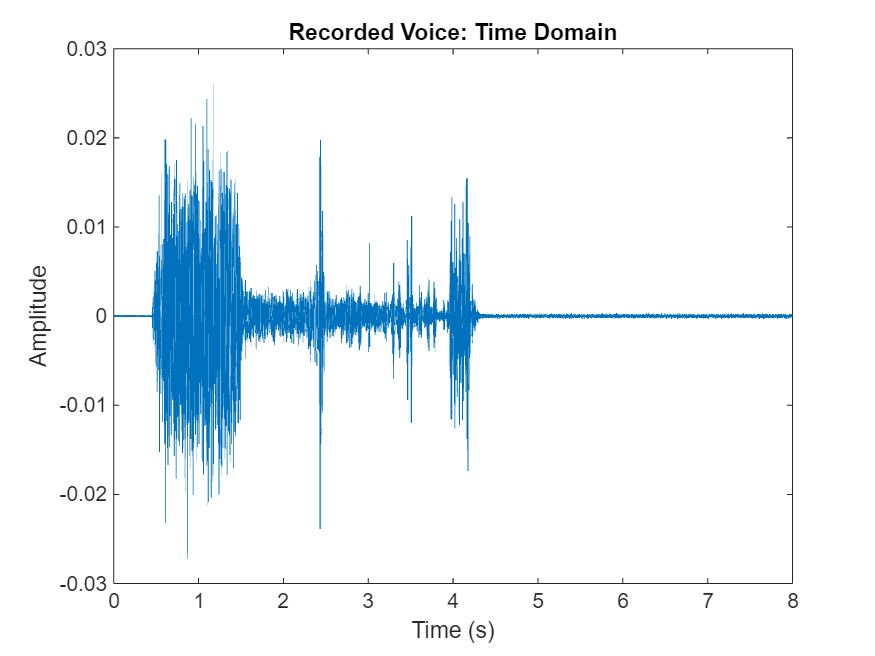

y = getaudiodata(recObj);
t = (0:length(y)-1) / Fs;
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Recorded Voice: Time Domain');

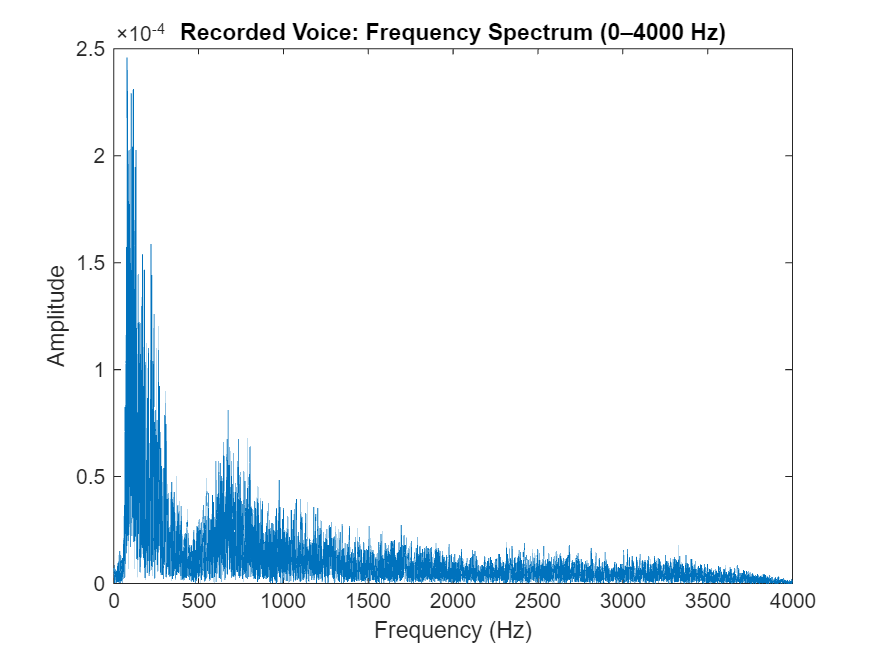

N = length(y);
Y = fft(y);
P2 = abs(Y)/N;
P1 = P2(1:floor(N/2)+1);         
P1(2:end-1) = 2*P1(2:end-1);
f = (0:floor(N/2)) * (Fs/N);
idx = (f <= 4000);
figure;
plot(f(idx), P1(idx));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Recorded Voice: Frequency Spectrum (0–4000 Hz)');
xlim([0 4000]);